# FIR Digital Filters

## Introduction to FIR digital filters

Digital finite impulse response (FIR) filter is defined by the following [input $x(n)$ $\rightarrow$ output $y(n)$] equation:


$$y(n) = \sum_{k=0}^{M} {b_{k}x(n-k)}$$


It represents a simplification of the IIR filter equation, i.e. the feedback term $\sum_{k=1}^{N} {a_{k}y(n-k)}$ is removed. Therefore an output sample $y(n)$ is only the weighted summation ("average") of last $M+1$ input samples $x(n-k)$, including the present one. Due to this operation the filter removes certain frequency components and it is: low-pass (LP), high-pass (HP), band-pass (BP) and band-stop (BS), depending on used $b_k$ values.

- Filter design = selection of coefficients $b_k$.

- Signal filtration = using weights $b_k$ in filter input-output equation.

The filter transfer function (TF) $H(z)$ is defined as ($z$ - variable of the Z transform, defined in the laboratory of IIR digital filters):

$H(z)=\frac{Y(z)}{X(z)}={{b}_{0}}+{{b}_{1}}{{z}^{-1}}+{{b}_{2}}{{z}^{-2}}+...+{{b}_{M}}{{z}^{-M}} = \left( 1-z_1z^{-1} \right)  \left( 1-z_1^*z^{-1} \right)  ... \left( 1-z_{M/2}z^{-1} \right)  \left( 1-z_{M/2}^*z^{-1} \right)$,

where $z_k$ denotes the polynomial roots which occur in pairs $\{ z_k, z_k^*\}$, in order to obtain real-value coefficients $b_k$. After setting:


$$z=e^{j 2 \pi (f/f_{s})$$


$f_s$ - sampling frequency, the H(z) converts to filter frequency response (FR) $H(f)$:

$H(f)=\frac{Y(f)}{X(f)}={{b}_{0}}+{{b}_{1}}{\left( e^{j 2 \pi (f/f_{s})} \right)^{-1}}+{{b}_{2}}{\left( e^{j 2 \pi (f/f_{s})} \right)^{-2}}}+...+{{b}_{M}}{{\left( e^{j 2 \pi (f/f_{s})} \right)^{-M}}}$.

**Example.**

*Input signal*:    $x(n)=A_0 \sin(2 \pi (f_0/f_{s}) n)$,

*Output signal*: $y(n)=(A_0 \cdot |H(f_0)|)  \cdot \sin(2 \pi (f_0/f_{s}) n+ \angle H(f_0)) =  (A_0 \cdot |H(f_0)|) \cdot \sin \left( 2 \pi (f_0/f_{s}) \left( n +  \frac {\angle H(f_0)}{2 \pi (f_0/f_{s})} \right) \right)$

i.e. the output signal is a sinusoid with the same frequency $f_0$ as on input BUT scaled in amplitude by $|H(f_0)|$ and shifted in phase by $\angle H(f_0) $ radians, what results in sine delay by $n_0 = \frac {\angle H(f_0)}{2 \pi (f_0/f_{s})}$  samples.

When the FIR filter has $M=2P+1$ weights/coefficients $b_k$ that are symmetrical (the same) albeit asymmetrical (the same values but negated) in regard to the central weight, the following things "happens":

- the phase response of the filter is linear,

- thanks to this all signal components are delayed on the filter output by $P$ samples,

- therefore, shape of the passed signal is not changed.

In this case the input sample $x(P+1)$corresponds to the output sample $y(2P+1)$, and so on, therefore the following correspondance between input and output samples exists:

`x=x(P+1:P+1+Nsamples-1)`    $\rightarrow$    `y=y(2*P+1:2*P+1+Nsamples-1)`.

 Knowledge about this effect, it is very important when we would like to synchronize filter output $y(n)$ with its input $x(n)$, for example when performing signal up-sampling or down-sampling (laboratory 10), or computing the analytic signal by means of FIR Hilbert filter (laboratory 11). Filter impulse response $h(k)$ is equal to the filter weights $b_k$.

**Analyze the Matlab code.** Choose different values of `b` and observe changes of: 1)  placement of `H(z)` polynomial roots `z `in relation to unitary circle $z=e^{j 2 \pi (f/f_{s})$, 2) complex-value frequency response `H(f)` of the filter, its abs(H) value (magnitude response) and angle(H) value (phase response). Test values of coefficients  `b`  returned by Matlab functions `fir1()`, `fir2()`, `firls()` and `firpm()`, when low-pass filter [0,100] Hz is designed. Use help command and read descriptions of two functions, choosen arbitrarily from four available by you. Try to design with their help the coefficients` b` of the band-pass filter [400,600] Hz. 

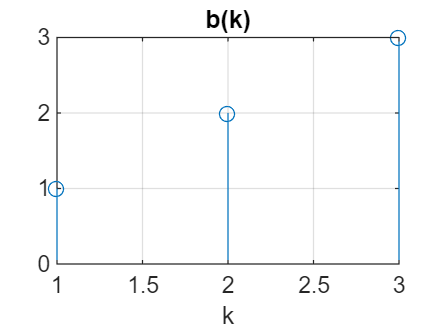

clear all; close all;

% Design of filter coefficients b
fs = 2000;                  % sampling frequency
M  = 101;                   % number of filter coeffs
 b = [ 1 2 3 ];             % filter/polynomial weights [b0, b1, b2, b3,...]
%b =  fir1(M, 100/(fs/2));  % window method: M coeffs, low-pass filter f0=100Hz 
%b =  fir2(M,[0 75 250 fs/2]/(fs/2),[1 1 0 0]);        % inverse DFT method: freq->gain
%b = firls(M,[0 75 250 fs/2]/(fs/2),[1 1 0 0],[1 10]); % optimal least-squares method
%b = firpm(M,[0 75 250 fs/2]/(fs/2),[1 1 0 0],[1 10]); % min of max error %method
	figure; stem(b); title('b(k)'); xlabel('k'); grid; % display of filter weights

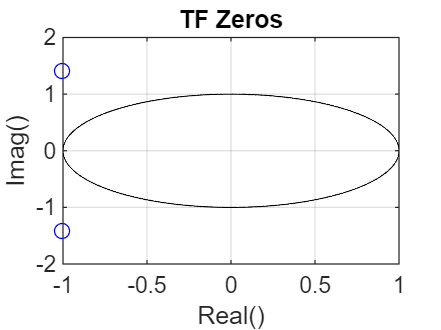

     
% Plot of H(z) zeros
z = roots(b);                   % roots of the nominator polynomial
    figure;
    var = 0 : pi/1000 : 2*pi; c=cos(var); s=sin(var);
    plot(real(z),imag(z),'bo', c,s,'k-'); grid;
    title('TF Zeros'); xlabel('Real()'); ylabel('Imag()');

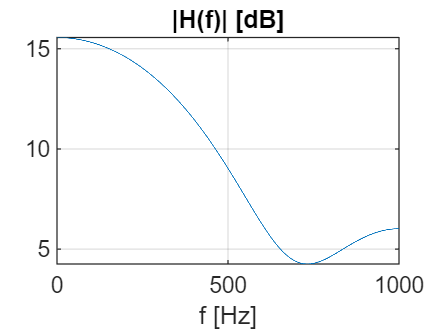


% Verification of filter responses: amplitude, phase, impulse, step
f = 0 : 0.1 : 1000;             % frequency in hertz
wn = 2*pi*f/fs;                 % radial normalized frequency
zz = exp(-j*wn);                % Z transform variable z^(-1)
H = polyval(b(end:-1:1),zz);    % H(f)=H(z) for z=exp(-j*wn): polynomial value
% H = freqz(b,1,f,fs)           % all-in-one Matlab function
    figure; plot(f,20*log10(abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;

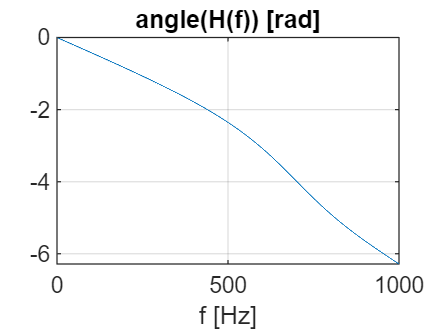

    figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;

## FIR digital filtering

Beeing conviced that the designed filter fullfil our requirements, let's use it for signal filtering. **Analyze the Matlab code**, run it, observe "signatures/waveforms" of an input and an output signal and their DFT frequency spectra. Is one of the signals completely rejected? Use Kronecker delta impulse as an input: compare shape of output samples with filter weights `b`. Use different input signals. May be your own speech?

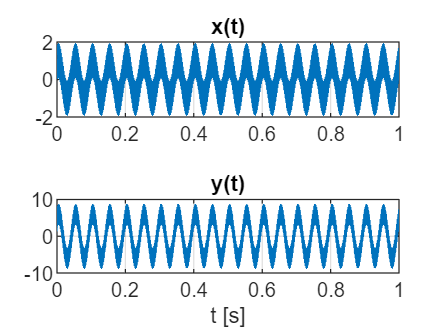

% Input signal x(n) - two sinusoids: 20 and 500 Hz
Nx = 2000;                                   % number of samples
dt = 1/fs; t = dt*(0:Nx-1);                  % sampling times
%x = zeros(1,Nx); x(1) = 1;                  % Kronecker delta impulse
x = sin(2*pi*20*t+pi/3) + sin(2*pi*500*t+pi/7);  % sum of 2 sines

% Digital FIR filtration: x(n) --> [ b, ] --> y(n)
M = length(b);                               % number of {b} coefficients
bx = zeros(1,M);                             % buffer for input samples x(n)
for n = 1 : Nx                               % MAIN LOOP
    bx = [ x(n) bx(1:M-1) ];                 % put new x(n) into bx buffer
    y(n) = sum( bx .* b );                   % do filtration, find y(n)
end                                          % 
%y = filter(b,1,x);                          % the same using filter()              
%y = conv(x,b);                              % the same using conv()
  
% FIGURES: comparison of input and output
figure;
subplot(211); plot(t,x); title('x(t)'); grid;     % input  signal x(t)
subplot(212); plot(t,y); title('y(t)'); grid;     % output signal y(t)
xlabel('t [s]');

figure; % signal spectra of the second halves of samples (transients are removed)
k=Nx/2+1:Nx;  f0 = fs/(Nx/2);  f=f0*(0:Nx/2-1); 
subplot(211); plot(f,20*log10(abs(2*fft(x(k)))/(Nx/2))); title('|X(f)| (dB)'); grid; 
subplot(212); plot(f,20*log10(abs(2*fft(y(k)))/(Nx/2))); title('|X(f)| (dB)'); grid;
xlabel('f (Hz)');    

## EXAMPLE:  derivation of the window method

### **Low-Pass (LP) filter design**

Since weights $b_k$ of an FIR digital filter are equal to its impulse response samples $h(k)$, therefore they can be calculated analytically by means of inverse DtFT transformation of the assumed/desired filter frequency response $H_{XX}(f)$ using the following formula (assuming $M=2P+1$, i.e. an odd filter length):

$h(k) = \frac{1}{f_{s}} \int\limits_{-f_{s}/2}^{f_{s}/2} {H_{XX}(f) {e}^{j \, 2\pi (f/f_{s})k} df} \quad \text{for} \;\; -P\le k \le P$.

For example, for the low-pass (LP) filter with cut-off frequency $f_0$:

- $H(f)=1 \; \text{for} f \leq f_0$ in the filter pass-band,

- $H(f)=0 \; \text{for} \; f > f_0$ in the filter stop-band.

Therefore, in this case, the last equation takes the following form (this time it is written for radial frequencies to make it more compressed, and $\Omega_0=2\pi \frac{f_0}{f_{s}}$):


$$h_{LP}^{(f_0)}(k)=\frac{1}{2\pi }\int\limits_{-\pi }^{\pi }{{{H}_{LP}}({{e}^{j\Omega}}){{e}^{j\Omega k}}d\Omega =\frac{1}{2\pi}}\int\limits_{-{{\Omega}_{0}}}^{{{\Omega}_{0}}}{1\cdot {{e}^{j\Omega k}}d\Omega }=\left. \frac{1}{2\pi }\frac{1}{jk}{{e}^{j\Omega k}} \right|_{\,-{{\Omega }_{0}}}^{\,{{\Omega }_{0}}}=\frac{1}{j2\pi k}\left[ {{e}^{j\Omega_{0} k}}-{{e}^{-j\Omega_{0} k}} \right]=$$


$=\frac{2j\sin ({{\Omega }_{0}}k)}{j2\pi k}=\frac{2j\sin ({{\Omega }_{0}}k)}{j2\pi k}= \frac{\sin (2\pi \frac{f_0}{f_{s}} k)}{\pi k}=2\frac{{{f}_{0}}}{{{f}_{s}}}\frac{\sin ({{\Omega }_{0}}k)}{{{\Omega }_{0}}k} \quad \text{for} \quad k=-P,...,-1,1,...,P$.

The above formula is not valid for $k=0$. From the de l'Hospital theorem (calculation of derivatives of nominator and denominator of the last ratio with respect to $k$) for this case we obtain:

$h_{LP}^{(f_0)}(0)=2 \frac{f_0}{f_{s}}$.

### **Design of HP, BP and BS filters**

Weights of other filter types (HP, BP, BS) are calculated knowing formula for $h_{LP}^{(f_{0})}(k)$ and weights $h_{ALL}(k)$of the all-pass filter $[0, f_s/2]$ which are equal: $h_{ALL}(0)=1, \;\; h_{ALL}(k \neq 0)=0$. They are  as follows ($f_1<f_2$):

- Low-Pass $\left[ 0, f_0 \right]$:                          $h_{LP}^{(f_{0})}(k)=2\frac{{{f}_{0}}}{{{f}_{s}}}\frac{\sin ({{\Omega }_{0}}k)}{{{\Omega }_{0}}k}$      

- High-Pass $\left[ f_0, f_s/2 \right]$:                    $h_{HP}^{(f_0)}(k)=h_{ALL}(k) - h_{LP}^{(f_0)}(k)$; 

- BandPass $[f_1, f_2]$:                        $h_{BP}^{([f_1,f_2])}(k)=h_{LP}^{(f_2)}(k) - h_{LP}^{(f_1)}(k)$;

- BandStop $[0,f_1]+[f_2,f_s/2]$:        $h_{BS}^{([f_1,f_2])}(k)=h_{ALL}(k) - h_{BP}^{([f_1,f_2])}(k)$

### **Additional remarks**

Causality. Calculated filter impulse response $h_{LP}^{(f_0)}(k)$ for $k=-P,...,0,...,P$ is not causal since the causal filter must have $h(k)=0 \;\; \text{for} \;\; k<0$. In order to obtain the causal filter, we shift the computed filter weights $P$ samples right (we make delay of $P$ samples), This results in the following multiplication of the original filter frequency response:

$H_{shifted}(f)=H(f) \cdot e^{-j 2\pi  (f/f_{s}) P}$,

i.e. linear decreasing of the final filter phase response with the rate depending on $P$.

Filter length and window choice. Longer filter (higher $P$) has sharper frequency cut-off edges in its amplitude response. Taking only $2P+1$ central filter weights (around $k=0$) we cut a fragment of the theoretical filter impulse - multiply it with rectangular cutting *observation window* function.  Multiplication in time domain corresponds to convolution in frequency domain. For this reason the ideal 0/1=stop/pass frequency response of the theoretical filter is convoluted with the $\frac{sin(\omega)}{\omega}$ oscillatory Fourier spectrum of the *rectangular window* and it is destroyed by it: it becomes oscillatory in the pass-band (around gain=1: in consequence the filter changes here signal shape) and in the stop-band (around gain=0: in consequence the filter has here bad attenuation). For this reason calculated filter weights $h(k)=b_k$ should be multiplied by specially chosen *window function*, for example Kaiser or Chebyshev (see laboratory 4 on DFT\&DtFT). 

### Exercise

**Analyze Matlab code** which is given below. Check implementation of derived above equations defining theoretical filter impulse responses. Run the program, observe figures. Apply the LP, HP, BP and BS filter weights, one by one, to the generated input signal. Observe that only: the 20~Hz (LP), the 500~Hz (HP),  the 500~Hz (BP) and once more the 20~Hz (BS) signal component is passed by different filters, respectively. Change filter length (longer filter has $|H(f)|$ with sharper transition edges from passing to stopping) and window used (windows improves the filter attenuation in the stop-band but makes its transition edges *from-pass-to-stop* less steep).

Use the Chebyshev window. Change level of spectral side-lobes attenuation in it, i.e. level of "ripples"  (`Rs=60, 80, 100, 120` dB) and plot frequency responses of four designed filters in one figure. Then set `Rs=100`~dB and choose different values of filter length `P=20,40,100,200,` and, again, plot frequency responses of four designed filters in one figure. Filter attenuation in the stop-band depends on window choice (confirm this with additional usage of `hanning(), blackman()` and `kaiser()` window) while width of the filter transition band from passing-to-stopping (the filter *sharpness*) depends on the filter length: longer filter are ``sharper''. 

Change values of cut-off frequencies of the filters.

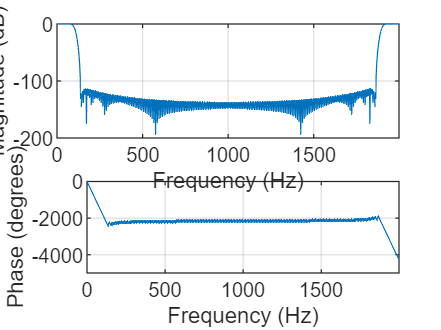

% Parameters
fs = 2000;       % sampling frequency
f0 = 100;        % cut-off frequency for low-pass and high-pass filters
f1 = 400;        % low frequency for band-pass and band-stop filters
f2 = 600;        % high frequency for band-pass and band-stop filters
P = 100;         % half of the filter weights
M = 2*P + 1;     % number of weights {b(n)} - always odd
k = -P :1: P;    % non-causal weights indexes

% Impulse responses - weights
hALL = zeros(1,M); hALL(P+1)=1;                          % AllPass
hLP = sin(2*pi*f0/fs*k)./(pi*k); hLP(P+1) = 2*f0/fs;     % LowPass f0
hHP = hALL - hLP;                                        % HighPass
hLP1 = sin(2*pi*f1/fs*k)./(pi*k); hLP1(P+1) = 2*f1/fs;   % LowPass f1
hLP2 = sin(2*pi*f2/fs*k)./(pi*k); hLP2(P+1) = 2*f2/fs;   % LowPass f2
hBP = hLP2 - hLP1;                                       % BandPass [f1,f2]
hBS = hALL - hBP;                                        % BandStop [f1,f2]
b = hLP;                                                 % choose: hLP, hHP, hBP, hBS
stem( k, b ); title('b(k)'); xlabel('k'); grid;
b = b .* chebwin(M,100)';    % Chebyshev window with -100 dB side-lobes
stem( k, b ); title('bw(k)'); xlabel('k'); grid;
freqz(b,1,f,fs);             % filter frequency response (magnitude and phase) 

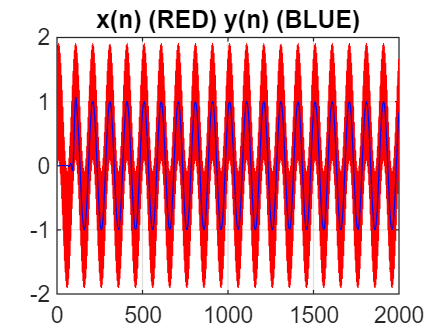

y = filter(b,1,x);           % signal filtering
figure; plot(1:Nx,x,'r-',1:Nx,y,'b-'); grid; title('x(n) (RED) y(n) (BLUE)');